clear;
clc;
close all;

## 1. Liste des valeurs de N à tester

N_values = [4 8 32 64];

nb_tests = length(N_values);

% Tableaux de stockage des résultats
h_values = zeros(nb_tests,1);
cond_values = zeros(nb_tests,1);
erreur_Linf_values = zeros(nb_tests,1);
erreur_L2_values = zeros(nb_tests,1);

## 2. Définition de la solution exacte et du second membre

% Solution exacte :
% u(x,y) = cos(pi*(x+y)) * sin(pi*(x-y))

uexact = @(x,y) cos(pi*(x+y)) .* sin(pi*(x-y));

% Second membre obtenu à partir de -Delta u = f

f = @(x,y) 2*pi^2 * ( sin(2*pi*x) - sin(2*pi*y) );

## 3. Boucle principale sur les différentes valeurs de N

for test = 1:nb_tests

## 3.1 Choix de N et calcul du pas h

    N = N_values(test);

    h = 1/(N+1);

    h_values(test) = h;

    fprintf('\n========================================\n');

    fprintf('Calcul pour N = %d\n', N);

Calcul pour N = 4


Calcul pour N = 8


Calcul pour N = 32


Calcul pour N = 64


    fprintf('Pas h = %.10e\n', h);

Pas h = 2.0000000000e-01


Pas h = 1.1111111111e-01


Pas h = 3.0303030303e-02


Pas h = 1.5384615385e-02


    fprintf('========================================\n');

## 3.2 Construction des points intérieurs

    x_int = h:h:1-h;
    y_int = h:h:1-h;

    [X_int, Y_int] = ndgrid(x_int, y_int);

## 3.3 Construction de la matrice A

    % Le schéma est :
    %
    % 4u(i,j) - u(i-1,j) - u(i+1,j) - u(i,j-1) - u(i,j+1)
    % =
    % h^2 f(x_i,y_j)

    e = ones(N,1);

    % Matrice tridiagonale associée à la direction x
    T = spdiags([-e 4*e -e], [-1 0 1], N, N);

    % Matrice identité
    I = speye(N);

    % Matrice associée aux couplages entre les blocs selon y
    B = spdiags([-e -e], [-1 1], N, N);

    % Matrice globale corrigée
    A = kron(speye(N), T) + kron(B, I);

## 3.4 Vérification rapide de la matrice pour N = 4

    if N == 4
        disp("Matrice A pour N = 4 :");
        disp(full(A));

        fprintf('Verification des signes :\n');
        fprintf('A(1,2) doit valoir -1 : %.0f\n', full(A(1,2)));
        fprintf('A(1,5) doit valoir -1 : %.0f\n', full(A(1,5)));
    end

Matrice A pour N = 4 :


     4    -1     0     0    -1     0     0     0     0     0     0     0     0     0     0     0
    -1     4    -1     0     0    -1     0     0     0     0     0     0     0     0     0     0
     0    -1     4    -1     0     0    -1     0     0     0     0     0     0     0     0     0
     0     0    -1     4     0     0     0    -1     0     0     0     0     0     0     0     0
    -1     0     0     0     4    -1     0     0    -1     0     0     0     0     0     0     0
     0    -1     0     0    -1     4    -1     0     0    -1     0     0     0     0     0     0
     0     0    -1     0     0    -1     4    -1     0     0    -1     0     0     0     0     0
     0     0     0    -1     0     0    -1     4     0     0     0    -1     0     0     0     0
     0     0     0     0    -1     0     0     0     4    -1     0     0    -1     0     0     0
     0     0     0     0     0    -1     0     0    -1     4    -1     0     0    -1     0     0
     0     0     0     0     0

Verification des signes :


A(1,2) doit valoir -1 : -1


A(1,5) doit valoir -1 : -1


## 3.5 Calcul du conditionnement

    cond_A = condest(A);

    cond_values(test) = cond_A;

    fprintf('Conditionnement cond(A) = %.10e\n', cond_A);

Conditionnement cond(A) = 1.3333333333e+01


Conditionnement cond(A) = 4.6295227525e+01


Conditionnement cond(A) = 6.4036199866e+02


Conditionnement cond(A) = 2.4886277450e+03


## 3.6 Construction du second membre F sous forme matricielle

    F = zeros(N,N);

    for j = 1:N
        for i = 1:N

            x = X_int(i,j);
            y = Y_int(i,j);

            % Terme principal h^2 f(x_i,y_j)
            F(i,j) = h^2 * f(x,y);

            % Contribution du bord gauche : x = 0
            if i == 1
                F(i,j) = F(i,j) + uexact(0,y);
            end

            % Contribution du bord droit : x = 1
            if i == N
                F(i,j) = F(i,j) + uexact(1,y);
            end

            % Contribution du bord inférieur : y = 0
            if j == 1
                F(i,j) = F(i,j) + uexact(x,0);
            end

            % Contribution du bord supérieur : y = 1
            if j == N
                F(i,j) = F(i,j) + uexact(x,1);
            end

        end
    end

## 3.7 Transformation de F en vecteur b

    % Ordre choisi :
    %
    % U = [u(1,1), u(2,1), ..., u(N,1),
    %      u(1,2), u(2,2), ..., u(N,N)]^T

    b = zeros(N*N,1);

    k = 1;

    for j = 1:N
        for i = 1:N

            b(k) = F(i,j);

            k = k + 1;

        end
    end

## 3.8 Résolution du système linéaire

    U = A\b;

## 3.9 Reconstruction de la solution numérique intérieure

    U_num_int = zeros(N,N);

    k = 1;

    for j = 1:N
        for i = 1:N

            U_num_int(i,j) = U(k);

            k = k + 1;

        end
    end

## 3.10 Calcul de la solution exacte aux points intérieurs

    U_exact_int = zeros(N,N);

    for j = 1:N
        for i = 1:N

            x = X_int(i,j);
            y = Y_int(i,j);

            U_exact_int(i,j) = uexact(x,y);

        end
    end

## 3.11 Calcul des erreurs aux points intérieurs

    Erreur_int = U_exact_int - U_num_int;

    % Norme infinie
    erreur_Linf = max(abs(Erreur_int(:)));

    % Norme L2 discrète
    erreur_L2 = sqrt(h^2 * sum(Erreur_int(:).^2));

    erreur_Linf_values(test) = erreur_Linf;
    erreur_L2_values(test) = erreur_L2;

    fprintf('Erreur L_inf = %.10e\n', erreur_Linf);

Erreur L_inf = 8.9882696121e-02


Erreur L_inf = 3.0608867089e-02


Erreur L_inf = 2.4226367107e-03


Erreur L_inf = 6.2500841918e-04


    fprintf('Erreur L2    = %.10e\n', erreur_L2);

Erreur L2    = 4.8914778324e-02


Erreur L2    = 1.4863805062e-02


Erreur L2    = 1.0982239719e-03


Erreur L2    = 2.8295356200e-04


## 3.12 Construction du maillage complet avec les bords

    x_full = 0:h:1;
    y_full = 0:h:1;

    [X_full, Y_full] = ndgrid(x_full, y_full);

## 3.13 Solution exacte sur le maillage complet

    U_exact_full = zeros(N+2,N+2);

    for j = 1:N+2
        for i = 1:N+2

            x = X_full(i,j);
            y = Y_full(i,j);

            U_exact_full(i,j) = uexact(x,y);

        end
    end

## 3.14 Construction de la solution numérique complète

    % On met d'abord la solution exacte partout.
    % Cela impose automatiquement les valeurs exactes sur les bords.

    U_num_full = U_exact_full;

    % Ensuite, on remplace les points intérieurs par la solution numérique.

    for j = 1:N
        for i = 1:N

            U_num_full(i+1,j+1) = U_num_int(i,j);

        end
    end

## 3.15 Erreur absolue sur le maillage complet

    Erreur_full = U_exact_full - U_num_full;

    Erreur_absolue_full = abs(Erreur_full);

## 3.16 Visualisations pour le N courant

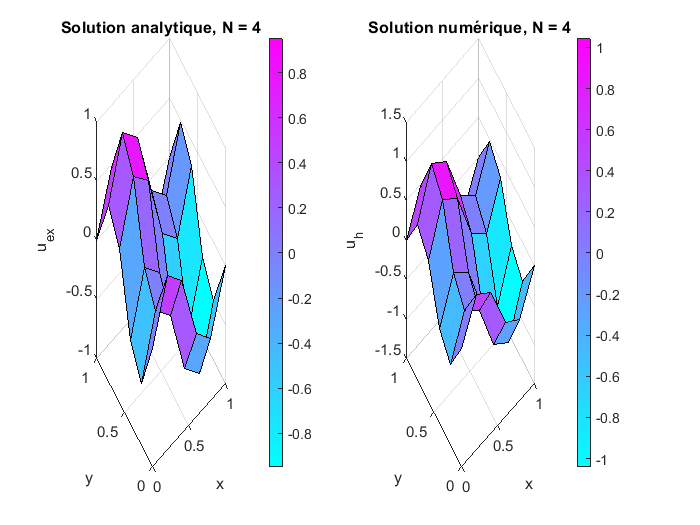

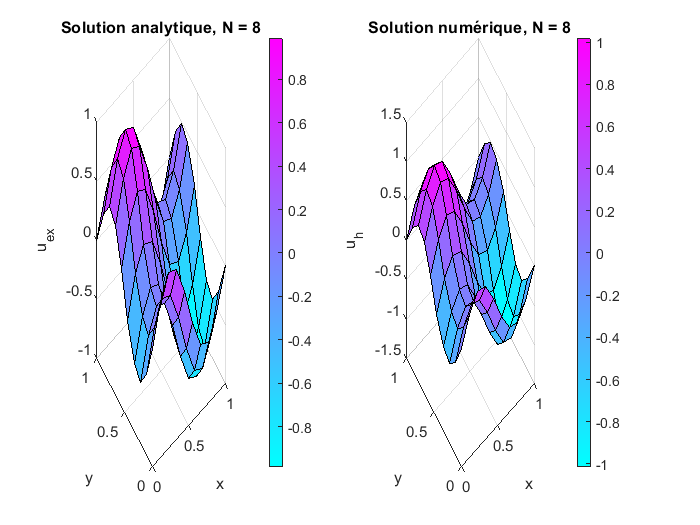

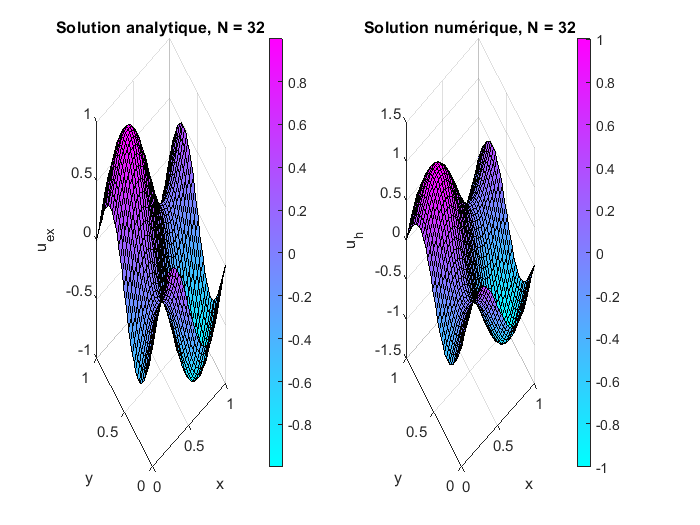

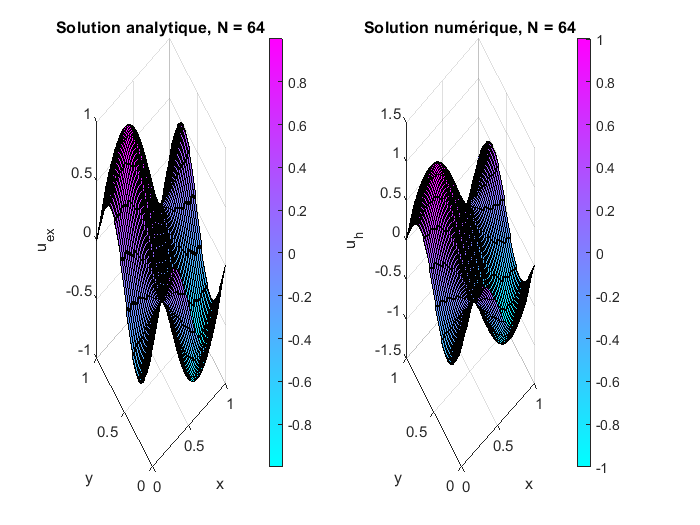

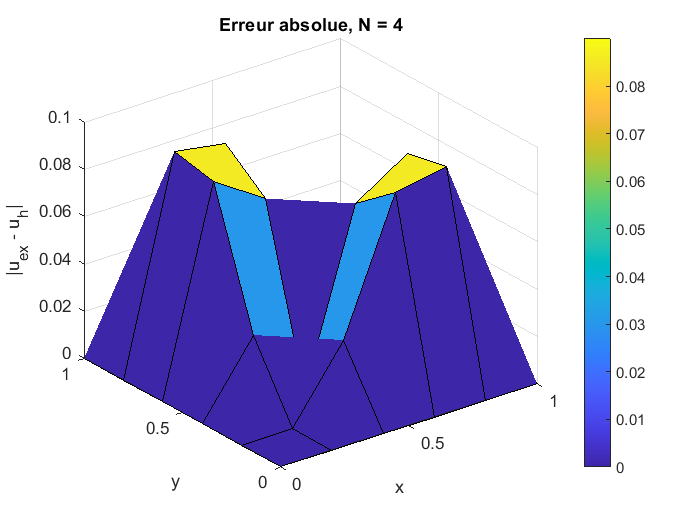

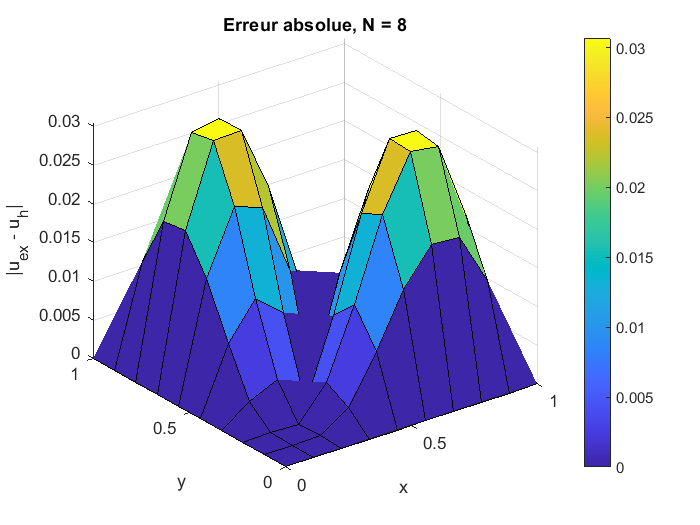

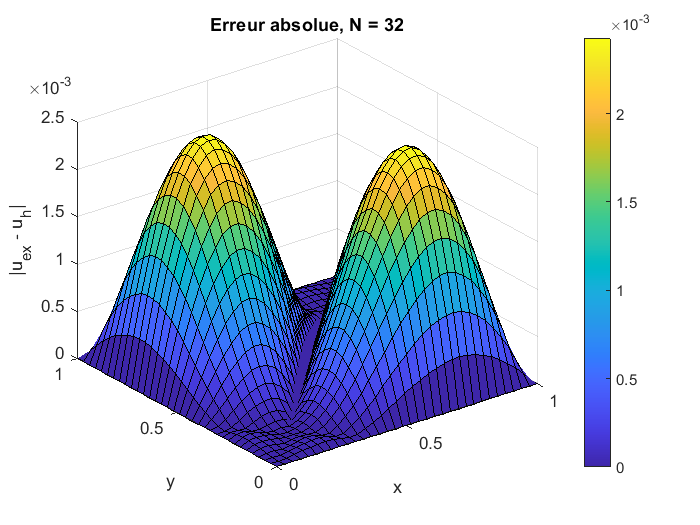

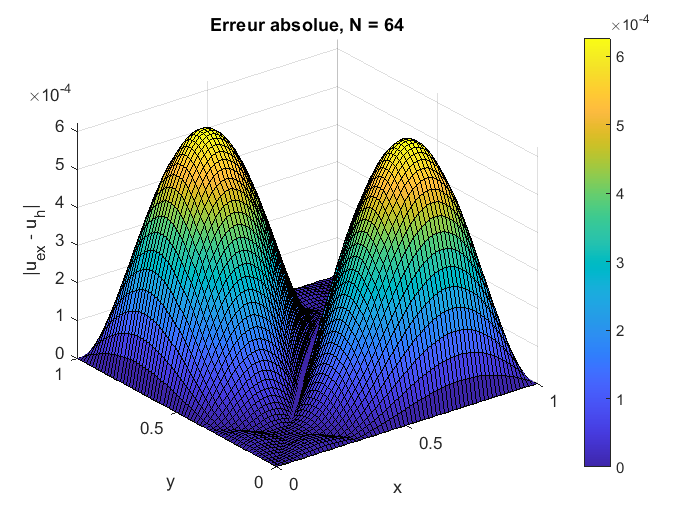

%% Visualisations pour N courant

% ============================================================
% 1) Comparaison : solution analytique et solution numérique
% ============================================================

figure('Name', sprintf('Comparaison des solutions pour N = %d', N));

subplot(1,2,1);

surf(X_full, Y_full, U_exact_full);

xlabel('x');
ylabel('y');
zlabel('u_{ex}');
title(sprintf('Solution analytique, N = %d', N));

colorbar;
grid on;


subplot(1,2,2);

surf(X_full, Y_full, U_num_full);

xlabel('x');
ylabel('y');
zlabel('u_h');
title(sprintf('Solution numérique, N = %d', N));

colorbar;
colormap('cool');
grid on;





% ============================================================
% 2) Erreur absolue seule
% ============================================================

figure('Name', sprintf('Erreur absolue pour N = %d', N));

surf(X_full, Y_full, Erreur_absolue_full);

xlabel('x');
ylabel('y');
zlabel('|u_{ex} - u_h|');
title(sprintf('Erreur absolue, N = %d', N));

colorbar;
grid on;




% ============================================================
% 3) Structure creuse de la matrice A seule
% ============================================================

figure('Name', sprintf('Structure creuse de A pour N = %d', N));

spy(A);

title(sprintf('Structure creuse de A, N = %d', N));



drawnow;


end

## ============================================================

Tableau_resultats = table( ...
    N_values', ...
    h_values, ...
    cond_values, ...
    erreur_Linf_values, ...
    erreur_L2_values, ...
    'VariableNames', {'N', 'h', 'Conditionnement', 'Erreur_Linf', 'Erreur_L2'} ...
);

disp(" ");

disp("Tableau récapitulatif des résultats :");

Tableau récapitulatif des résultats :


disp(Tableau_resultats);

    N        h        Conditionnement    Erreur_Linf    Erreur_L2 
    __    ________    _______________    ___________    __________

     4         0.2        13.333           0.089883       0.048915
     8     0.11111        46.295           0.030609       0.014864
    32    0.030303        640.36          0.0024226      0.0010982
    64    0.015385        2488.6         0.00062501     0.00028295



## ============================================================

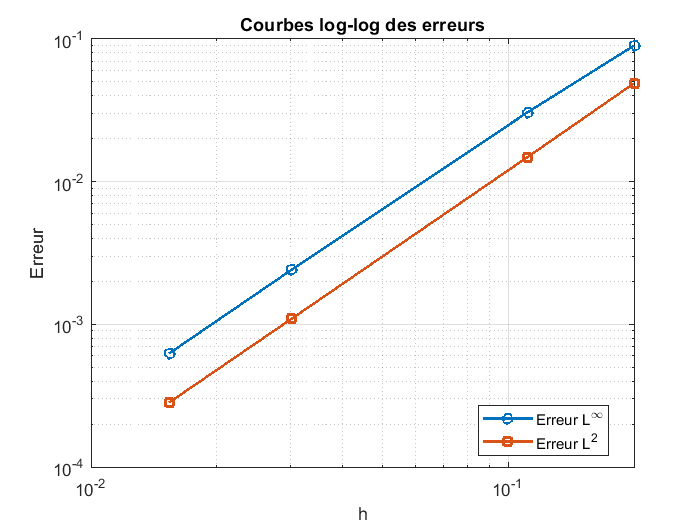

figure('Name', 'Courbes log-log des erreurs');

loglog(h_values, erreur_Linf_values, '-o', 'LineWidth', 1.5);
hold on;

loglog(h_values, erreur_L2_values, '-s', 'LineWidth', 1.5);

grid on;

xlabel('h');
ylabel('Erreur');

title('Courbes log-log des erreurs');

legend('Erreur L^\infty', 'Erreur L^2', 'Location', 'best');

## ============================================================


%% Estimation de l'ordre de convergence p

% On suppose une loi de convergence de la forme :
% Erreur(h) ≈ C * h^p
% En échelle logarithmique :
% log(Erreur) ≈ log(C) + p log(h)
% Donc p est la pente de la droite log-log.

coeff_Linf = polyfit(log(h_values), log(erreur_Linf_values), 1);
coeff_L2   = polyfit(log(h_values), log(erreur_L2_values), 1);

ordre_Linf = coeff_Linf(1);
ordre_L2   = coeff_L2(1);

fprintf('\n');
fprintf('Ordre estime en norme Linf : %.4f\n', ordre_Linf);

Ordre estime en norme Linf : 1.9407


fprintf('Ordre estime en norme L2   : %.4f\n', ordre_L2);

Ordre estime en norme L2   : 2.0080


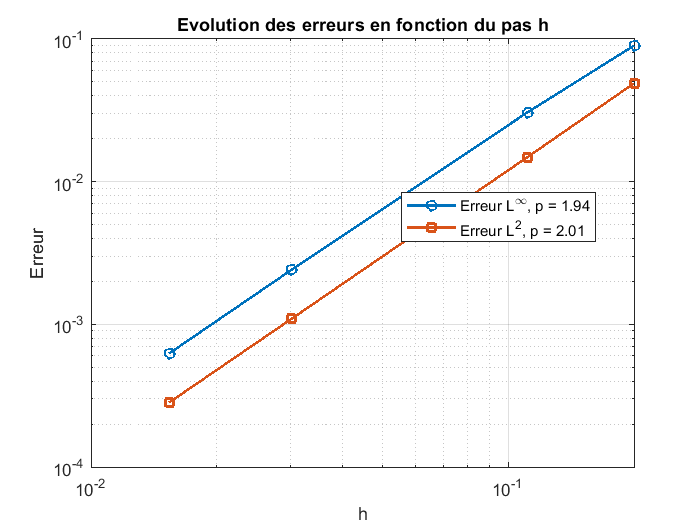




figure('Name', 'Courbes log-log des erreurs');

loglog(h_values, erreur_Linf_values, '-o', 'LineWidth', 1.5);
hold on;

loglog(h_values, erreur_L2_values, '-s', 'LineWidth', 1.5);

grid on;

xlabel('h');
ylabel('Erreur');
title('Evolution des erreurs en fonction du pas h');

legend( ...
    sprintf('Erreur L^\\infty, p = %.2f', ordre_Linf), ...
    sprintf('Erreur L^2, p = %.2f', ordre_L2), ...
    'Location', 'best' ...
);

## ============================================================

% Si erreur ≈ C h^p, alors :
%
% log(erreur) ≈ log(C) + p log(h)
%
% La pente p donne l'ordre de convergence.

p_Linf = polyfit(log(h_values), log(erreur_Linf_values), 1);
ordre_Linf = p_Linf(1);

p_L2 = polyfit(log(h_values), log(erreur_L2_values), 1);
ordre_L2 = p_L2(1);

fprintf('\n========================================\n');

fprintf('ORDRES DE CONVERGENCE\n');

ORDRES DE CONVERGENCE


fprintf('========================================\n');

fprintf('Ordre en norme L_inf = %.6f\n', ordre_Linf);

Ordre en norme L_inf = 1.940718


fprintf('Ordre en norme L2    = %.6f\n', ordre_L2);

Ordre en norme L2    = 2.007990


fprintf('========================================\n');

## ============================================================

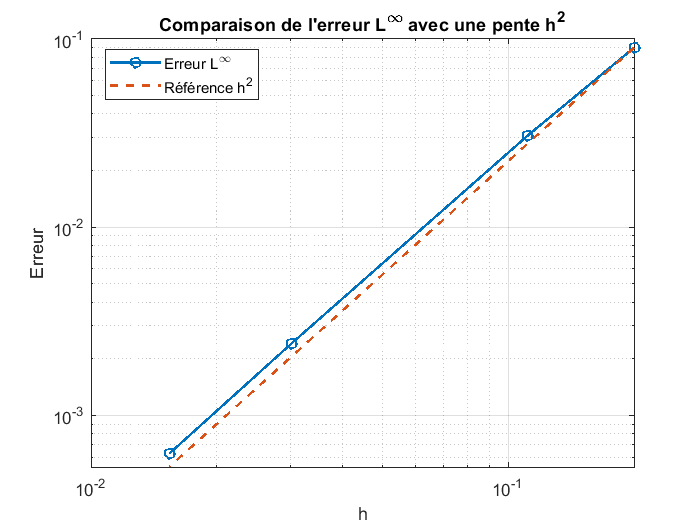

% Pour comparer visuellement avec une convergence d'ordre 2,
% on trace une droite proportionnelle à h^2.

reference_h2 = erreur_Linf_values(1) * (h_values / h_values(1)).^2;

figure('Name', 'Comparaison avec une pente h^2');

loglog(h_values, erreur_Linf_values, '-o', 'LineWidth', 1.5);
hold on;

loglog(h_values, reference_h2, '--', 'LineWidth', 1.5);

grid on;

xlabel('h');
ylabel('Erreur');

title('Comparaison de l''erreur L^\infty avec une pente h^2');

legend('Erreur L^\infty', 'Référence h^2', 'Location', 'best');